clear
% simultion of 4 metagriding

## constants


eta = 377; %ohm
f= 10*10^9; %Hz
c = 3*10^8; %m/s
lambda = c/f;
k = 2*pi/lambda;
omega = 2*pi*f;
w = 0.0254e-3; % meters, 1 mil
reff = w/4;


## paramters


theta_in = 15*pi/180; %rads
theta_out = 60*pi/180;% rads
phi = 25*pi/180; % rads
Ein = 1;

sinin = sin(theta_in);
cosin = cos(theta_in);
sinout = sin(theta_out);
cosout = cos(theta_out);

Zin = eta/cos(theta_in);
Zout = eta/cos(theta_out);
Lambda = lambda/abs(sinout-sinin);


## vars


I = sym('I', [4 1]);
d = sym('d', [1,4]);
h = sym('h', [1,4]);
syms sin_in sin_out cos_in cos_out Z_in Z_out phase Lam K;
% phase = exp(1j*phi)
% Lam = Lambda*E_in 


## equations  - current as a function of everything


eq1 = exp(1j*K*(sin_in*d+cos_in*h))*I == 2*Lam/Z_in;
eq2 = exp(1j*K*(sin_out*d+cos_out*h))*I == 0;
eq3 = exp(1j*K*(sin_in*d-cos_in*h))*I == 0;
eq4 = exp(1j*K*(sin_out*d-cos_out*h))*I == 2*Lam*phase/Z_out;
eqns = [eq1,eq2,eq3,eq4];
Currents = solve(eqns,I);
Is1 = subs(Currents.I1,[sin_in sin_out cos_in cos_out Z_in Z_out phase Lam K],[sinin sinout cosin cosout Zin Zout exp(1j*phi) Lambda*Ein k]);
Is2 = subs(Currents.I2,[sin_in sin_out cos_in cos_out Z_in Z_out phase Lam K],[sinin sinout cosin cosout Zin Zout exp(1j*phi) Lambda*Ein k]);
Is3 = subs(Currents.I3,[sin_in sin_out cos_in cos_out Z_in Z_out phase Lam K],[sinin sinout cosin cosout Zin Zout exp(1j*phi) Lambda*Ein k]);
Is4 = subs(Currents.I4,[sin_in sin_out cos_in cos_out Z_in Z_out phase Lam K],[sinin sinout cosin cosout Zin Zout exp(1j*phi) Lambda*Ein k]);
Is=[Is1,Is2,Is3,Is4];


## Optimization parameters

x0=[0,0,0,0.1*lambda,0.2*lambda,0.3*lambda];
N=10;
save('var.mat');

## Optimization

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    5.643692e+08    0.000e+00    1.024e+13


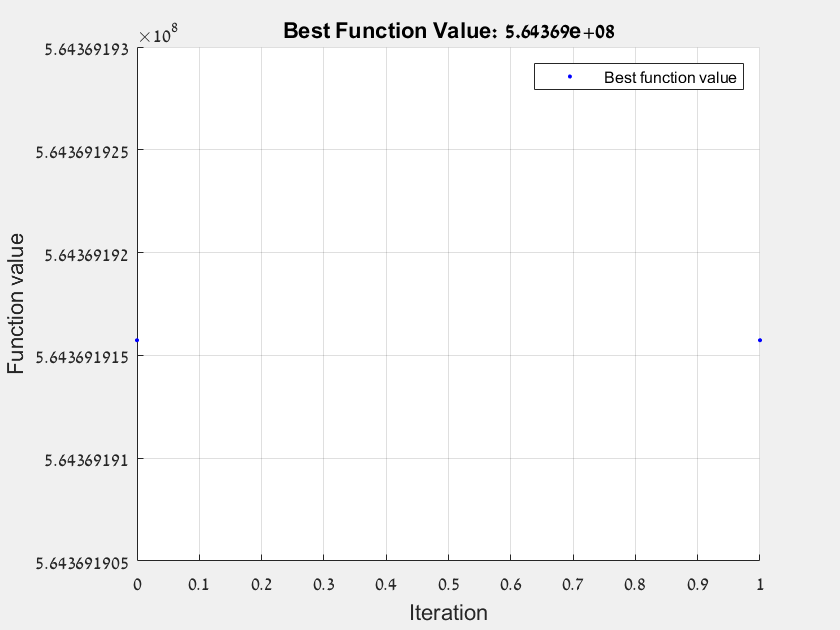


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Set nondefault solver options
options = optimoptions('fmincon','Display','iter','PlotFcn',...
    'optimplotfvalconstr');

% Solve
[solution,objectiveValue] = fmincon(@objectiveFcn,x0,[],[],[],[],[],[],...
    @constraintFcn,options);


% Clear variables
clearvars options

## optimization function

function f = objectiveFcn(optimInput)

load('var.mat');
% Edit the lines below with your calculation
D2 = optimInput(1);
D3 = optimInput(2);
D4 = optimInput(3);
H2 = optimInput(4);
H3 = optimInput(5);
H4 = optimInput(6);

Is2 = double(subs(Is, [d h],[[0 mod(D2,Lambda) mod(D3,Lambda) mod(D4,Lambda)] [0 mod(H2,lambda) mod(H3,lambda) mod(H4,lambda)]]));
Fields = FindElectricFiield(Lambda,k,eta,theta_in,Ein,[0 mod(D2,Lambda) mod(D3,Lambda) mod(D4,Lambda)],[0 mod(H2,lambda) mod(H3,lambda) mod(H4,lambda)],Is2,reff,N);
Impadences= Fields'./Is2;
f= sum((real(Impadences)).^2);
end


## costrains


function [c,ceq] = constraintFcn(optimInput)
load('var.mat');
% Example:
% Constrain a solution to the region
% h2 <= h3
% h3 <= h4
% y = x^3

% Edit the lines below with your calculation
% Note, if no inequality constraints, specify c = []
% Note, if no equality constraints, specify ceq = []

H2 = optimInput(4);
H3 = optimInput(5);
H4 = optimInput(6);

c(1) = H2 - H3;
c(2) = H3 - H4;
c(3) = - H2;

ceq = [];
end

